# **Hydrogen Deflagration Experiments**

# Data Processing Procedure (DPP)

## **Objectives**

Hydrogen deflagration time-series Analysis to determine maximum peak overpressure **∆Pmax [kPa]**.

## Procedure Overview

Units SI

### 1. Data Preparation

### 2. Exploratory Data Analysis (EDA)

2.1 Time Domain

2.2 Frequency Domain

### 3. Signal Preprocessing

3.1 Design a Low-Pass Filter

### 4. Quantity of Interest (QoI) Extraction of **∆Pmax [kPa] after Filtering**

## Matlab Startup File

This m-File code prepare the enviroment to provide access to auxilliary files and sub-folders.

clear; clc; close all;
format short eng                              
% Plot Colors
LUCopper = [147, 86, 14]/255;LUCopper_Light = [225, 213, 199]/255;LUBlue = [17, 55, 125]/255;LUBlue_Light = [197, 204, 221]/255;
Red_Dark = [192, 0, 0]/255;Red_Light = [235, 200, 197]/255;pink = [255, 199, 206]/255;skyblue_light=[183/255 236/255 255/255];

## 1. Data Preparation 

### 1.1 Import Signal Data 

Load "Raw" Signal

**Note: **Details on DAQ system setting are required, to check if any hardware filters has been used.

load('E2038.mat');  
dataRMH = cases;  % [g]
dataPraw = p * 100; % [kPa]

### **1.2 Baseline/Offset Assessment **

Identify any baseline offset and decide on necessary baseline correction.

Offset correction based on the** first 100 samples.**

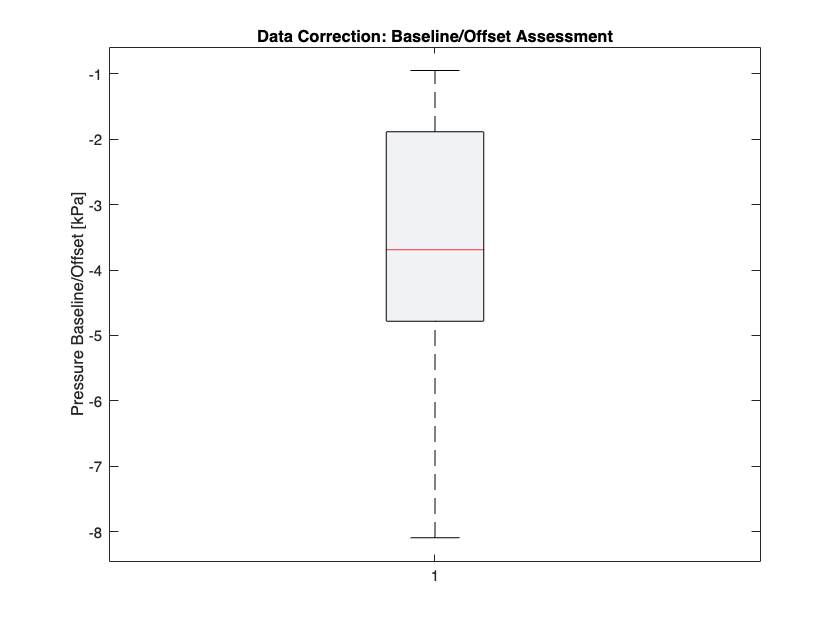

nSamples = 100;
Fs = fs;             % Sampling frequency in Hz
t = ((0:length(dataPraw)-1)'/Fs); % [s] Time Vector Uniform sample
DC_offset = mean(dataPraw(1:nSamples,:), 1);% [kPa]
figure;
boxplot(DC_offset);
h = findobj(gca,'Tag','Box');
patch(get(h,'XData'),get(h,'YData'),LUBlue_Light,'FaceAlpha',.25);
ylabel('Pressure Baseline/Offset [kPa]')
box on
title('Data Correction: Baseline/Offset Assessment')

### **1.3 DC-Offset-Correction**

Pressure reading corrected (offset/baseline removed)

dataP = dataPraw - DC_offset;

## 2. Exploratory Data Analysis (EDA)

### **2.1 Released Mass of Hydrogen [g]** 

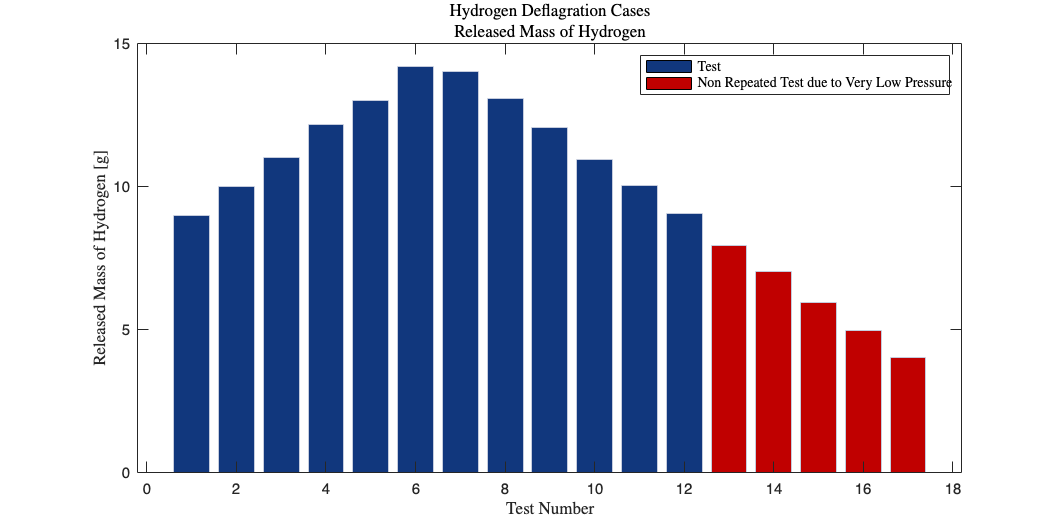

testNum = 1:length(dataRMH);
% Define custom colors for boundary conditions
bar_colors = [LUBlue; Red_Dark];
% Case Staus
Case_Staus = {'Test', 'Non Repeated Test due to Very Low Pressure'};
% Create the bar plot with 'flat' FaceColor for per-bar coloring
figure;
x0=10;
y0=10;
width=25;
height=12.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height])
barPlot = bar(testNum, dataRMH, 'FaceColor', 'flat', 'EdgeColor', LUBlue_Light);

% Set default color for all bars
defaultColor = bar_colors(1,:); % Ensure this is an RGB triplet
barPlot.CData = repmat(defaultColor, length(dataRMH), 1);

% Define indices of bars to change and their new color
indicesToChange = 13:1:17; % Example indices
newColor = bar_colors(2,:); % Example: red; replace with desired RGB triplet

% Update colors for selected bars
barPlot.CData(indicesToChange, :) = repmat(newColor, numel(indicesToChange), 1);

% AuxFcn_Figure_Settings('Test Number','Released Mass of Hydrogen [g]',''...
%     ,{'Hydrogen Deflagration Cases','Released Mass of Hydrogen'},12)
xlabel('Test Number','Interpreter','latex')
ylabel('Released Mass of Hydrogen [g]','Interpreter','latex')
title({'Hydrogen Deflagration Cases','Released Mass of Hydrogen'},'Interpreter','latex')

% Add legend manually using "dummy" bars
hold on;
legend_handles = gobjects(length(Case_Staus),1);  % Create empty objects for legend
for i = 1:length(Case_Staus)
    legend_handles(i) = bar(nan, nan, 'FaceColor', bar_colors(i, :)); % Create dummy bars for legend
end
legend(legend_handles, Case_Staus, 'Location', 'northeast','Interpreter','latex');

### 2.2 Time Domain Analysis

#### Corrected Pressure Signal (DC-Offset-Corrected)

Compute Pressure max, and min across each test (column-wise)

[pMax, idx] = max(dataP, [], 1); % [kPa]
pMaxT = t(idx); % [ms]
[pMin, idx] = min(dataP, [], 1); % [kPa]
pMinT = t(idx); % [ms]

Compute Impulse and Signal Energy [kPa.ms]

impulseP = trapz(t, dataP)';

Impulse Check by Cumulative

impulseP_check = cumtrapz(t, dataP)';
Icheck = (impulseP_check(:,end)./impulseP) * 100;
% figure;
% plot(t,impulseP_check(12,:));  % Should show a smooth increasing function
% hold off

Compute Signal Energy [kPa^2]

energySignal = sum(abs(dataP).^2)';  % Total energy

Table Summary

dataSummary = table(testNum',round(dataRMH',2), round(pMax',1),pMaxT, round(pMin',1),pMinT,round(impulseP,1),round(energySignal,1), ...
    'VariableNames', {'Test Number','Released Mass of Hydrogen [g]', 'Pmax. [kPa]','Pmax.Time[s]', 'Pmin. [kPa]','Pmin.Time[s]', 'Impulse [kPa.s]','Signal Energy [kPa^2]'});
disp(dataSummary);

    Test Number    Released Mass of Hydrogen [g]    Pmax. [kPa]    Pmax.Time[s]    Pmin. [kPa]    Pmin.Time[s]    Impulse [kPa.s]    Signal Energy [kPa^2]
    ___________    _____________________________    ___________    ____________    ___________    ____________    _______________    _____________________

         1                      8.99                    2.3           0.5377             -1         0.38271             0.3                2.509e+05      
         2                        10                    2.7          0.54684           -0.8         0.53392             0.3                2.073e+05      
         3                     11.03                   12.4          0.20379           -8.9         0.21879

### 2.3 Frequency Domain Analysis

#### 2.3.1 General Considerations

**1. Deflagration Pressure Signals Have Dominant Low-Frequency Components**

- The **overpressure rise** in deflagration events is often **gradual** compared to high-frequency noise.

- The **dominant physical processes** (combustion expansion, flame acceleration, venting effects) evolve on timescales much longer than **sensor vibrations or electronic noise**.

**2. Common Sources of High-Frequency Noise**

- **Sensor Vibrations & Structural Resonances:**

- Pressure transducers, particularly those mounted on rigid test chambers, can pick up **high-frequency mechanical vibrations**.

- **Electrical Noise:**

- Data acquisition (DAQ) systems and amplification circuits introduce **high-frequency interference**.

- **Shock-Induced Transients (if present):**

- If a strong shock develops, it may introduce **high-frequency components**, but **for deflagrations**, most of the pressure signal energy is **low-frequency**.

**3. Why a Low-Pass Filter is Appropriate?**

- The primarily interested in: 

- **Peak overpressure** **∆Pmax**�

- **Impulse (integral of pressure over time)**

- **Time of peak pressure, **not as relevant as ∆Pmax, however, it is still considered a good metric to consider in the evaluation of the Low-Pass FIlter Effect during the Data Processing Procedure.

- These **key metrics** are **not affected by removing high-frequency noise**.

- A properly chosen **low-pass cutoff frequency** ensures the removal unwanted noise while **preserving** the physically meaningful pressure rise.

**4. Consideration for Cutoff Frequency Selection**

This is a challenge aspec of th edata processing due to the lack of knlodges about the frequencies a that migh tdominate the phenomena, however, several assumption required to be made.

- The **filter cutoff frequency** should be: 

- **Well above** the dominant deflagration pressure rise rate.

- **Below** the typical noise frequency components.

- A **frequency-domain analysis** (FFT or EWT) of the raw pressure signal) help to **identify the frequencies present in each test and determine** an **appropriate cutoff frequency.**

**Remark**

**Applying a low-pass filter makes sense** for the deflagration experiments **as long as the cutoff frequency is chosen appropriately**. To ensures that it is captured the **pressure response** while removing high-frequency noise that does not represent physical pressure changes.

#### 2.3.2 Empirical Wavelet Transform (EWT) [3]

**Extracted from Matlab**

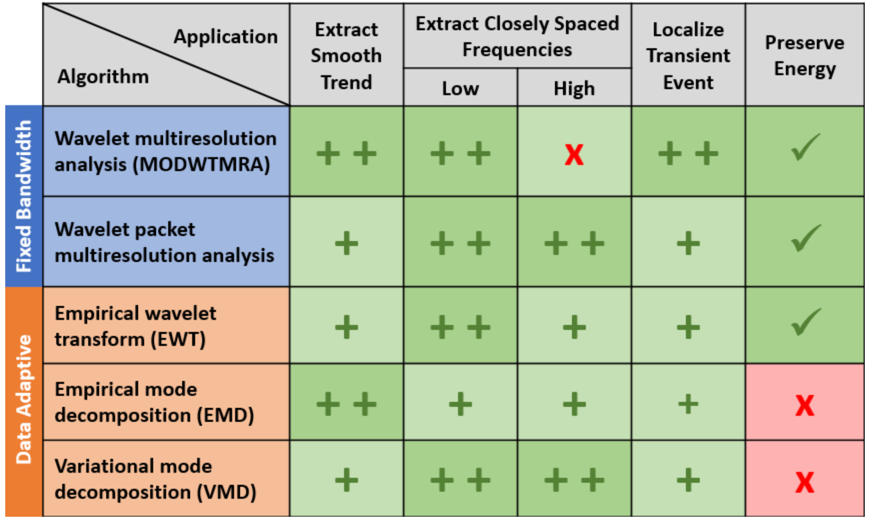

The key thing to note is that similar to the wavelet and EMD decompositions, VMD segregates the three components of interest into completely separate modes or into a small number of adjacent modes. All three techniques allow you to visualize signal components on the same time scale as the original signal. There is a data-adaptive technique which actually constructs wavelet filters based on the frequency content of the data. This technique is the *empirical wavelet transform *(EWT) [3]. One of the major criticisms of EMD is that its definition is purely algorithmic. As a result, it is not readily amenable to mathematical analysis. EWT on the other hand actually constructs Meyer wavelets based on the frequency content of the analyzed signal. Accordingly, the results of EWT are amenable to mathematical analysis because the filters used in the analysis are available to the user. Repeat the analysis of the synthetic signal using the EWT.

#### Signal Decomposition by MRA using EWT

#### Intrinsic Mode Functions (IMF)

exampleTest = 3;
MaxNumPeaks = 5;
results = struct(); % Store results for each test
summaryData = []; % Initialize numerical data matrix

        fprintf('Processing Test %d...\n', exampleTest);

Processing Test 3...


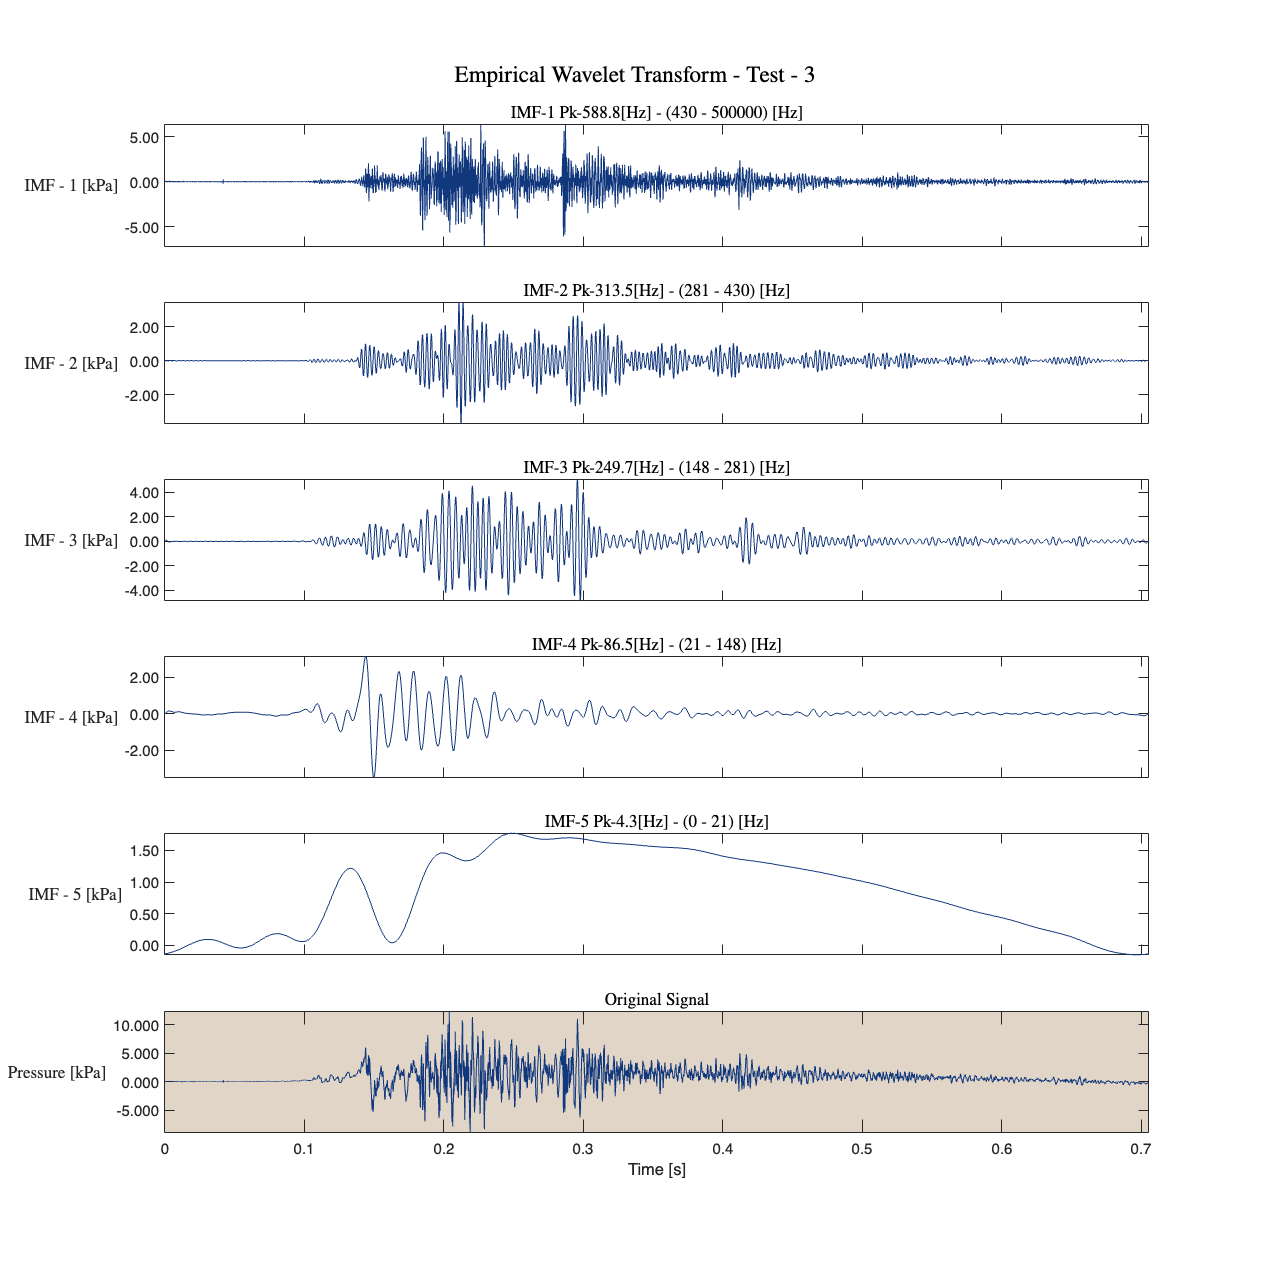

        % Perform EWT on the selected test
        [mra_ewt, cfs, wfb, info] = ewt(dataP(:, exampleTest), 'MaxNumPeaks',MaxNumPeaks);
        % Convert peak frequencies and passbands to Hz
        PeakFrequencies = Fs * info.PeakFrequencies;
        freqPassbands = Fs * info.FilterBank.Passbands;
        % Store results for each test
        results(i).TestNumber = exampleTest;
        results(i).MRA = mra_ewt;
        results(i).Coefficients = cfs;
        results(i).WaveletBank = wfb;
        results(i).PeakFrequencies = PeakFrequencies;
        results(i).Passbands = freqPassbands;

        %% Signal Reconstruction  
        % Logical array for selecting reconstruction elements
        levelForReconstruction = [false,false,false,false,true];
        % levelForReconstruction = [false,true,true,true,true,true,true,true,true,true];
        % Sum down the rows of the selected multiresolution signals
        results(i).SignalRecon = sum(mra_ewt(:,levelForReconstruction),2);

        %% Signal Reconstruction Verification
        % Verify that summing the MRA components results in perfect reconstruction of the signal.
        results(i).SignalReconCheck = max(abs(dataP(:, exampleTest)-sum(mra_ewt,2)));
        
        % Verify energy preservation of the EWT analysis coefficients.
        signalEnergy = norm(dataP(:, i),2)^2;
        cfsenergy = sum(sum(abs(cfs).^2));
        results(i).Energy= [signalEnergy cfsenergy];
        results(i).EnergyPreservRelDiffCheck= ((cfsenergy- signalEnergy)/signalEnergy) * 100;% [%]

        % Append numerical data for structured table
        numModes = length(PeakFrequencies);
        for j = 1:numModes
            summaryData = [summaryData; i, j, PeakFrequencies(j), freqPassbands(j,1), freqPassbands(j,2)];
        end  
figure
    x0=10;
    y0=10;
    width = 75;
    height = 15 * MaxNumPeaks;
    set(gcf,'units','centimeters','position',[x0,y0,width,height])
    signal = subplot(MaxNumPeaks+1,1,MaxNumPeaks+1);
    plot(t,dataP(:,exampleTest),'Color',LUBlue);
    ytickformat('%.3f')  
    ax = gca;
    ax.YAxis.Exponent = 0;  % Disables scientific notation
    ylimMax = max(dataP(:, exampleTest));
    ylimMin = min(dataP(:, exampleTest));
    ylim([ylimMin + ylimMin * 0.2  ylimMax + ylimMax * 0.2 ])  
    % p.XTickLabel={};
    % signal = gca;
    signal.Color = LUCopper_Light;
    signal.YLabel.Rotation = 0;
    signal.YLabel.HorizontalAlignment = 'right';
    signal.YLabel.VerticalAlignment = 'middle';
    title('Original Signal','Interpreter','latex')
    sgtitle(['Empirical Wavelet Transform - Test - ',num2str(exampleTest)],'Interpreter','latex')
    ylabel('Pressure [kPa]','Interpreter','latex')
    xlabel('Time [s]')
    axis tight
    for k=1:MaxNumPeaks
        modes = subplot(MaxNumPeaks+1,1,k);
        plot(t,mra_ewt(:,k),'Color',LUBlue)
        ylabel(['IMF -  ',num2str(k), ' [kPa]'],'Interpreter','latex')
        ytickformat('%.2f')  
        ax = gca;
        ax.YAxis.Exponent = 0;  % Disables scientific notation 
        % ytickformat('auto')
        ylimMax = max(mra_ewt(:,k));
        ylimMin = min(mra_ewt(:,k));
        ylim([ylimMin + ylimMin * 0.2  ylimMax + ylimMax * 0.2 ])  
        modes.YLabel.Rotation = 0;
        modes.YLabel.HorizontalAlignment = 'right';
        modes.YLabel.VerticalAlignment = 'middle';
        % ylabel('Pressure [mbar]')
        % title(sprintf("EWT - IMF %d", k))
        title(['IMF-' num2str(k) ' Pk-' num2str(PeakFrequencies(k), '%.1f') '[Hz]' ' - ' ' (' num2str(freqPassbands(k,1), '%.0f') ' - ' num2str(freqPassbands(k,2), '%.0f') ') [Hz]'],'Interpreter','latex')
        axis tight
        % s.XTickLabel={};
        set(gca,'xticklabel',[])
    end

**References**

[1] Dragomiretskiy, Konstantin, and Dominique Zosso. “Variational Mode Decomposition.” *IEEE Transactions on Signal Processing* 62, no. 3 (February 2014): 531–44. [https://doi.org/10.1109/TSP.2013.2288675](https://doi.org/10.1109/TSP.2013.2288675).

[2] Flandrin, P., G. Rilling, and P. Goncalves. “Empirical Mode Decomposition as a Filter Bank.” *IEEE Signal Processing Letters* 11, no. 2 (February 2004): 112–14. [https://doi.org/10.1109/LSP.2003.821662](https://doi.org/10.1109/LSP.2003.821662).

[3] Giles, J. "Empirical wavelet transform", *IEEE Transactions on Signal Processing, *vol. 61, no. 16 (May 2013): 3999 - 4010. 

[4] Huang, Norden E., Zheng Shen, Steven R. Long, Manli C. Wu, Hsing H. Shih, Quanan Zheng, Nai-Chyuan Yen, Chi Chao Tung, and Henry H. Liu. “The Empirical Mode Decomposition and the Hilbert Spectrum for Nonlinear and Non-Stationary Time Series Analysis.” *Proceedings of the Royal Society of London. Series A: Mathematical, Physical and Engineering Sciences* 454, no. 1971 (March 8, 1998): 903–95. [https://doi.org/10.1098/rspa.1998.0193](https://doi.org/10.1098/rspa.1998.0193).

[5] Percival, Donald B., and Andrew T. Walden. *Wavelet Methods for Time Series Analysis*. Cambridge Series in Statistical and Probabilistic Mathematics. Cambridge ; New York: Cambridge University Press, 2000.

*Copyright 2019 The MathWorks, Inc.*

## 3. Signal Preprocessing

### 3.1 Design of a  Low-Pass Filter 

**Butterworth Filter** (IIR: Infinite Impulse Response Type)

#### 3.1.1 Low-Pass Filter Phase Delay Effect

Minimum Filter Order

lfCut = 500;
% Given parameters
Fs = fs;   % Sampling frequency in Hz
fc = lfCut;   % Passband cutoff frequency (Hz)
fs_stop = fc + 500; % Stopband frequency (Hz)
Rp = 3;      % Maximum ripple in passband (dB)
Rs = 40;     % Minimum stopband attenuation (dB)
% Normalize frequencies to Nyquist frequency (Fs/2)
Wp = fc / (Fs/2);
Ws = fs_stop / (Fs/2);


Compute minimum Butterworth filter order

[filter_order, Wn] = buttord(Wp, Ws, Rp, Rs);

lpFilt = designfilt('lowpassiir', ...
    'FilterOrder', filter_order, ...
    'HalfPowerFrequency', lfCut, ...
    'DesignMethod','butter',...
    'SampleRate', Fs);

Zero-phase filtering

dataLowPass = filtfilt(lpFilt, dataP(:,exampleTest));
dataLowPassPhaseDelay = filter(lpFilt,dataP(:,exampleTest));

Low-Pass Filter Phase Delay Effect Plot

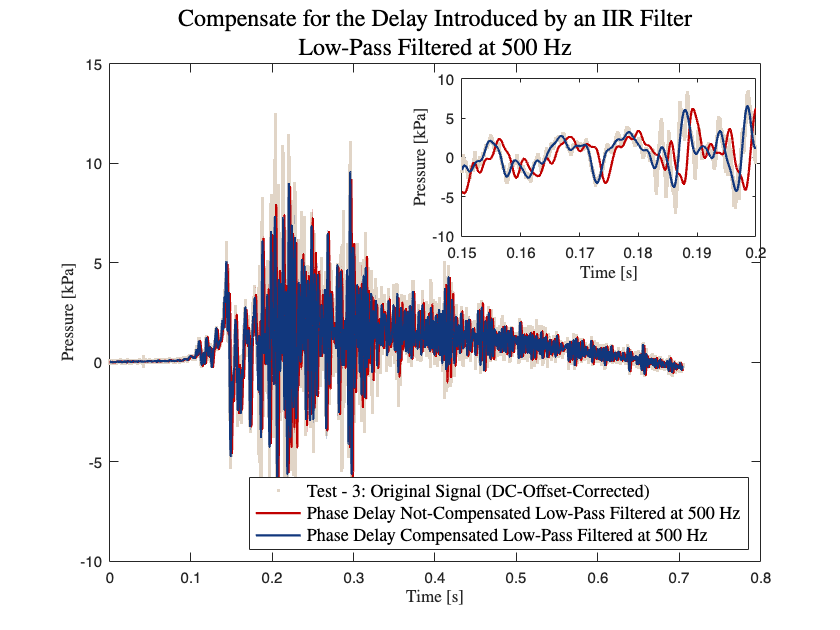

figure;
scatter(t, dataP(:,exampleTest), '.', ...
    'MarkerEdgeColor', LUCopper_Light, ...
    'MarkerEdgeAlpha', 1);   % Original signal
hold on;

plot(t, dataLowPassPhaseDelay, 'LineWidth', 1.5, 'Color', Red_Dark); 
plot(t, dataLowPass, 'LineWidth', 1.5, 'Color', LUBlue); 

title({"Compensate for the Delay Introduced by an IIR Filter", ...
       sprintf("Low-Pass Filtered at %.0f Hz", lfCut)}, 'fontsize', 16,'Interpreter','latex');
xlabel('Time [s]','Interpreter','latex'); 
ylabel('Pressure [kPa]','Interpreter','latex');
legend(sprintf('Test - %d: Original Signal (DC-Offset-Corrected)', exampleTest), ...
       sprintf("Phase Delay Not-Compensated Low-Pass Filtered at %.0f Hz", lfCut),...
       sprintf("Phase Delay Compensated Low-Pass Filtered at %.0f Hz", lfCut),...
       'Location','southeast', 'FontSize', 12,'Interpreter','latex');
box on;

% ---- ZOOMED-IN INSET ----
zoom_start = 0.15; % Adjust this range to zoom in on phase delay effects
zoom_end = 0.20;
zoom_idx = (t >= zoom_start) & (t <= zoom_end);

axes('Position', [0.55, 0.625, 0.35, 0.25]); % Adjust position/size of inset
% axes('Position', [0.2, 0.625, 0.25, 0.25]); % Adjust position/size of inset
hold on;
scatter(t(zoom_idx), dataP(zoom_idx,exampleTest), '.', 'MarkerEdgeColor', LUCopper_Light);
plot(t(zoom_idx), dataLowPassPhaseDelay(zoom_idx), 'LineWidth', 1.5, 'Color', Red_Dark);
plot(t(zoom_idx), dataLowPass(zoom_idx), 'LineWidth', 1.5, 'Color', LUBlue); 
% title('Zoomed View','Interpreter','latex');
xlabel('Time [s]','Interpreter','latex');
xlim([0.15 0.20])
ylabel('Pressure [kPa]','Interpreter','latex');
box on;
hold off

#### 3.1.2 Low-Pass Filter Sensitivty Analysis

Define Cutoff Frequencies & Filter Orders to Test 

**Perform Empirical Wavelet Transform (EWT)**

MaxNumPeaks = 25; % Set max number of peaks for adaptive segmentation
[mra, cfs, wfb, info] = ewt(dataP(:,exampleTest), 'MaxNumPeaks', MaxNumPeaks);

**Extract Peak Frequencies and Passbands & Filter Design**

PeakFrequencies = Fs * info.PeakFrequencies;
freqPassbands = Fs * info.FilterBank.Passbands;
cutoff_frequencies = PeakFrequencies;  % Test 10 different cutoff frequencies
n = zeros(size(cutoff_frequencies,1),1);
for i = 1:length(cutoff_frequencies)
    % Given parameters
    fc = cutoff_frequencies(i);   % Passband cutoff frequency (Hz)
    fs_stop = cutoff_frequencies(i) + 500; % Stopband frequency (Hz)
    Rp = 3;      % Maximum ripple in passband (dB)
    Rs = 40;     % Minimum stopband attenuation (dB)

    % Normalize frequencies to Nyquist frequency (Fs/2)
    Wp = fc / (Fs/2);
    Ws = fs_stop / (Fs/2);

    % Compute minimum Butterworth filter order
    n(i) = buttord(Wp, Ws, Rp, Rs);
end
nMin = max(n);
filter_orders = [nMin, nMin + 2, nMin + 4, nMin + 6];  % Filter orders

#### Matrices to store results

% Memory Allocation
energy_ratio_matrix = zeros(length(filter_orders), length(cutoff_frequencies));
impulse_ratio_matrix = zeros(length(filter_orders), length(cutoff_frequencies));
peak_pressure_ratio_matrix = zeros(length(filter_orders), length(cutoff_frequencies));
peak_pressure_T_ratio_matrix = zeros(length(filter_orders), length(cutoff_frequencies));

%% Apply Low-Pass Filtering for Different Cutoff Frequencies & Orders
for f_idx = 1:length(filter_orders)
    for c_idx = 1:length(cutoff_frequencies)
        fc = cutoff_frequencies(c_idx);  % Current cutoff frequency
        filter_order = filter_orders(f_idx);  % Current filter order
        lpFilt = designfilt('lowpassiir', ...
        'FilterOrder', filter_order, ...
        'HalfPowerFrequency', fc, ...
         'DesignMethod','butter',...
        'SampleRate', Fs);
        % Zero-phase filtering
        p_filtered = filtfilt(lpFilt, dataP(:,exampleTest));
        % Compute energy, impulse, and peak pressure after filtering
        E_filtered = sum(abs(p_filtered).^2);
        Impulse_filtered = trapz(t, p_filtered);
        [PeakPressure_filtered, idx] = max(p_filtered, [], 1); 
        PeakPressure_filtered_T = t(idx); % [ms]

        % Store results as ratio (%)
        energy_ratio_matrix(f_idx, c_idx) = (E_filtered / energySignal(exampleTest)) * 100;
        impulse_ratio_matrix(f_idx, c_idx) = (Impulse_filtered / impulseP(exampleTest)) * 100;
        peak_pressure_ratio_matrix(f_idx, c_idx) = (PeakPressure_filtered / pMax(exampleTest)) * 100;
    end
end


**Plot Results: Low-Pass Filter Order & Cuttoff Frequency Analysis**

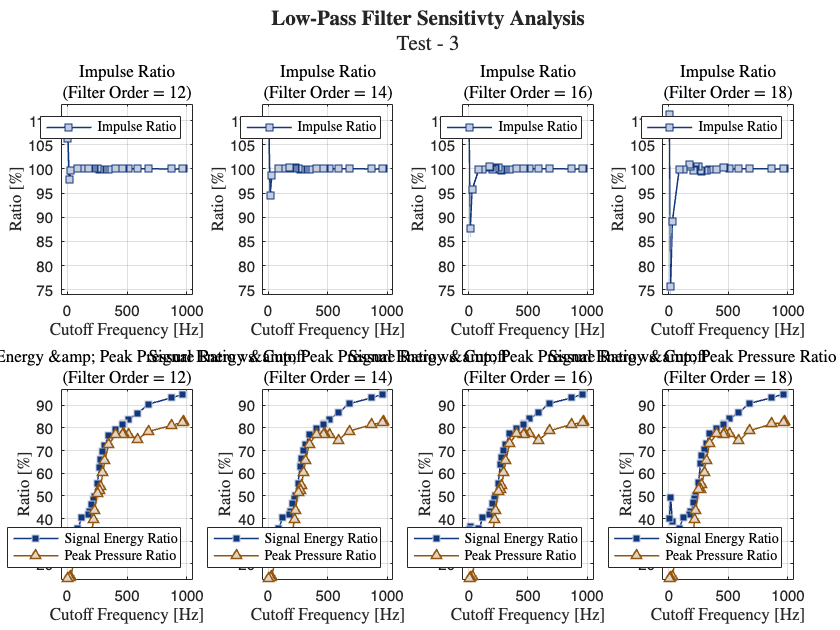

figure;
tiledlayout(2,4, 'TileSpacing', 'compact', 'Padding', 'compact'); % Define 2 rows, 4 columns

for f_idx = 1:length(filter_orders)
    % Top row: Impulse Ratio
    nexttile(f_idx); % Assigns first 4 tiles for impulse ratio
    plot(cutoff_frequencies, impulse_ratio_matrix(f_idx, :), '-s','Color',LUBlue,'MarkerFaceColor',LUBlue_Light,'MarkerEdgeColor',LUBlue, 'LineWidth', 1);
    xlabel('Cutoff Frequency [Hz]', 'Interpreter', 'latex');
    % xlim([-10 max(cutoff_frequencies) * 1.05]);
    xlim([-50 1050]);
    ylabel('Ratio [\%]', 'Interpreter', 'latex');
    ylim([min(min(impulse_ratio_matrix(:, :))) * 0.98, max(max(impulse_ratio_matrix(:, :))) * 1.02]); % Adds slight margin
    % ylim([75 115]); % Adds slight margin
    title({'Impulse Ratio',['(Filter Order = ' num2str(filter_orders(f_idx)) ')']},'Interpreter', 'latex');
    legend('Impulse Ratio', 'Location', 'northeast', 'Interpreter', 'latex');
    grid on;

    % Bottom row: Energy Ratio & Peak Pressure Ratio
    nexttile(f_idx + 4); % Assigns tiles 5-8 for energy/pressure ratio
    plot(cutoff_frequencies, energy_ratio_matrix(f_idx, :), '-s','Color',LUBlue,'MarkerFaceColor',LUBlue,'MarkerEdgeColor',LUBlue_Light, 'LineWidth', 1); hold on;
    plot(cutoff_frequencies, peak_pressure_ratio_matrix(f_idx, :), '-^','Color',LUCopper,'MarkerEdgeColor',LUCopper,'MarkerFaceColor',LUCopper_Light, 'LineWidth', 1);hold on;

    % plot(cutoff_frequencies, peak_pressure_T_ratio_matrix(f_idx, :), ':v','Color',LUCopper,'MarkerEdgeColor',LUCopper_Light,'MarkerFaceColor',LUCopper, 'LineWidth', 1);
    hold off;
    
    xlabel('Cutoff Frequency [Hz]', 'Interpreter', 'latex');
    % xlim([0 max(cutoff_frequencies) * 1.02]);
    xlim([-50 1050]);
    ylabel('Ratio [\%]', 'Interpreter', 'latex');
    ylim([min(min([peak_pressure_ratio_matrix(:, :);energy_ratio_matrix(:, :)])) * 0.98 max(max([peak_pressure_ratio_matrix(:, :);energy_ratio_matrix(:, :)])) * 1.02]); % More generous spacing
    title({'Signal Energy \& Peak Pressure Ratio vs. Cutoff',[' (Filter Order = ', num2str(filter_orders(f_idx)), ')']},'Interpreter', 'latex');
    % legend('Signal Energy Ratio', 'Peak Pressure Ratio','Peak Pressure Time Shift Ratio', 'Location', 'southeast', 'Interpreter', 'latex');
    legend('Signal Energy Ratio', 'Peak Pressure Ratio','Location', 'southeast', 'Interpreter', 'latex');
    grid on;
end
sgtitle({'\textbf{Low-Pass Filter Sensitivty Analysis}',sprintf('Test -  %d', exampleTest)},'fontsize',14, 'Interpreter', 'latex')
hold off;

## 4. Quantity of Interest (QoI) Extraction of **∆Pmax [kPa] after Filtering**

### 4.1 Define CutOff Frequencies & Minimum Filter Order

cutoff_frequencies = 250:50:1000;
nMin = zeros(size(cutoff_frequencies,1),1);
for i = 1:length(cutoff_frequencies)
    % Given parameters
    fc = cutoff_frequencies(i);   % Passband cutoff frequency (Hz)
    fs_stop = cutoff_frequencies(i) + 500; % Stopband frequency (Hz)
    Rp = 3;      % Maximum ripple in passband (dB)
    Rs = 40;     % Minimum stopband attenuation (dB)

    % Normalize frequencies to Nyquist frequency (Fs/2)
    Wp = fc / (Fs/2);
    Ws = fs_stop / (Fs/2);

    % Compute minimum Butterworth filter order
    nMin(i) = buttord(Wp, Ws, Rp, Rs);
end
filter_orders = nMin;  % Filter orders

### 4.2 Calculation **∆Pmax [kPa] after Filtering**

% Memory Allocation
peakPressureFiltered = zeros(length(cutoff_frequencies), length(testNum));
%% Apply Low-Pass Filtering for Different Cutoff Frequencies & Filter Orders
for t_idx = 1:length(testNum)
    for fc_idx = 1:length(cutoff_frequencies)
        fc = cutoff_frequencies(fc_idx);  % Current cutoff frequency
        filter_order = filter_orders(fc_idx);  % Current filter order
        lpFilt = designfilt('lowpassiir', ...
        'FilterOrder', filter_order, ...
        'HalfPowerFrequency', fc, ...
         'DesignMethod','butter',...
        'SampleRate', Fs);
        % Zero-phase filtering
        pressureFiltered = filtfilt(lpFilt, dataP(:,t_idx));
        
        % Compute Peak pressure after filtering
        [peakPressureFiltered(fc_idx, t_idx), idx] = max(pressureFiltered, [], 1); % [kPa]
    end
end
DeltaP_max = max(peakPressureFiltered);

### 4.3 Plot **∆Pmax [kPa] after Filtering**

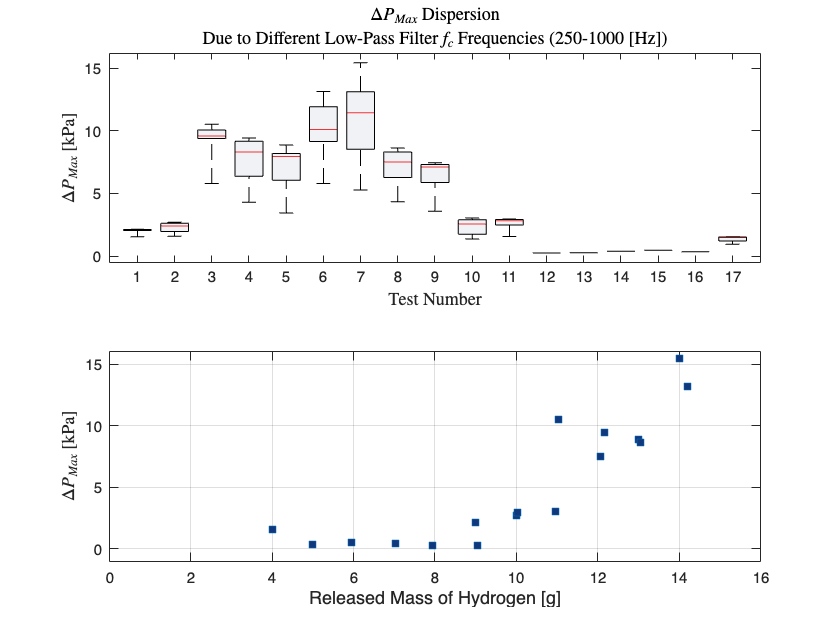

figure;
subplot(2,1,1)
boxplot(peakPressureFiltered, 'Whisker', Inf, 'Widths',.75);
h = findobj(gca,'Tag','Box');
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),LUBlue_Light,'FaceAlpha',.25);
end

xlabel('Test Number','Interpreter','latex','FontSize',12)
ylabel ('$\Delta P_{Max}$ [kPa]','Interpreter','latex','FontSize',12)
title({'$\Delta P_{Max}$ Dispersion','Due to Different Low-Pass Filter $f_{c}$ Frequencies (250-1000 [Hz])'},'Interpreter','latex','FontSize',12)
box on
subplot(2,1,2)
scatter(dataRMH, DeltaP_max, 's','MarkerFaceColor',LUBlue); % Overlay mean values
hold on
ylabel ('$\Delta P_{Max}$ [kPa]','Interpreter','latex','FontSize',12)
xlabel('Released Mass of Hydrogen [g]','FontSize',12)
xlim([0 16])
ylim([-1 16])
grid on
box on
hold off

% Linear Fit

% % Data
% x = dataRMH; % Replace with your x-data (Hydrogen mass)
% y = DeltaP_max;   % Replace with your y-data (Max pressure change)
% 
% 
% % Fit a linear model
% mdl = fitlm(x, y); 
% 
% % Generate new x-values for smooth plotting
% xFit = linspace(min(x), max(x), 100)'; % 100 points for smooth curve
% 
% % Predict y-values and get confidence intervals
% [yFit, yCI] = predict(mdl, xFit, 'Alpha', 0.05); % 95% confidence level
% 
% % Plot the original data
% figure;
% scatter(x, y, 's', 'MarkerFaceColor', LUBlue, 'MarkerEdgeColor', LUBlue_Light); hold on;
% 
% % Plot the fitted line
% plot(xFit, yFit, '-','Color',Red_Dark, 'LineWidth', 2, 'DisplayName', 'Linear Fit');
% 
% % Fill the confidence interval area
% fill([xFit; flipud(xFit)], [yCI(:,1); flipud(yCI(:,2))], Red_Dark, ...
%     'FaceAlpha', 0.2, 'EdgeColor', 'none', 'DisplayName', '95\% CI');
% 
% % Labels and legend
% xlabel('Released Mass of Hydrogen [g]');
% ylabel('\Delta P_{max} [kPa]');
% title('Linear Fit with 95% Confidence Interval');
% legend('Data', 'Linear Fit', '95\% CI', 'Location', 'northwest');
% grid on;
% hold off;
